# MEJORA Y FILTRADO DE IMÁGENES EN EL DOMINIO DEL ESPACIO EN MATLAB

Las técnicas de filtrado eliminan ruido de las imágenes a través del filtrado. El mejor método para una situación dada depende de la imagen y del tipo de ruido o degradación. Así, a modo de ejemplo, tenemos:

-Los** filtros lineales** proporcionan simplicidad y velocidad, y son los más útiles cuando el ruido está limitado a una banda de frecuencia conocida.

-Los **filtros mediana** son muy efectivos para eliminar el ruido ‘salt & pepper’, píxeles a uno y cero de valores muy diferentes a los de los píxeles de su entorno.

-Los **filtros Wiener** son filtros lineales adaptativos basados en las características de varianza locales de la imagen. Suavizan gradualmente, cambiando las áreas de la imagen donde el ruido es muy aparente, y manteniendo aquellas donde hay muchos detalles y el ruido es menos aparente.

Todas las funciones de restauración de imágenes trabajan con imágenes de intensidad (niveles de gris). Para aplicar estos algoritmos sobre imágenes de color, es necesario procesar las componentes rojo, verde y azul independientemente.

## Comprender filtros espaciales en MATLAB.

En MATLAB, un filtro FIR bidimensional es un array ordenado de coeficientes, h(n1,n2), que pueden introducirse en MATLAB como una matriz:

h   =   [0     0    1     0    0

           0     1    4     1    0

           1     4   -24   4    1

           0     1    4     1    0

           0     0    1     0    0];

Esta representación del filtro es conocida como “**máscara**”. La función de la toolbox *filter2* implementa el filtrado FIR bidimensional aplicando la máscara a los datos de la imagen. 

## Diseño de filtros espaciales.

A continuación se procederá a filtrar una imagen en el dominio del espacio con diversas máscaras de efectos diferentes. 

Primero se va a utilizar un filtro de **promediado** en el que el valor que cada píxel de la imagen de salida es la media de los del entorno en la imagen de entrada:

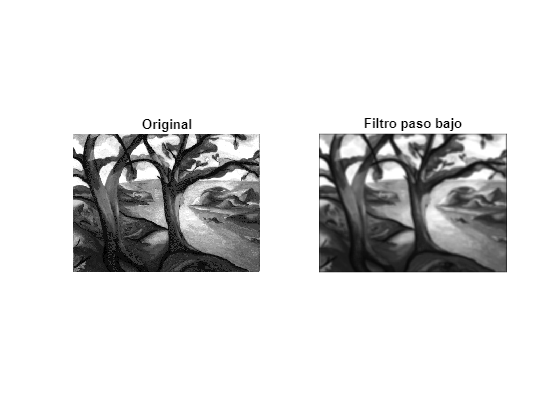

% Filtrado espacial de una imagen con máscara
load trees;
I=ind2gray(X,map); %Se trabaja con una imagen a nivel de gris double [0 1]
h=1/25*[1 1 1 1 1;1 1 1 1 1;1 1 1 1 1;1 1 1 1 1;1 1 1 1 1] ; %Definición de la máscara. Filtro paso bajo
Y=filter2(h,I); %Por defecto, obtiene filtrado tras centrar "h" en píxeles dentro de la imagen de entrada
% Y=filter2(h,I,'full'); %Obtiene el resultado completo del filtrado. Mas informacion: help filter2
figure, subplot(1,2,1),imshow(I),title('Original');
subplot(1,2,2),imshow(Y),title('Filtro paso bajo');

Se puede obtener la respuesta frecuencial del filtro mediante la función: 

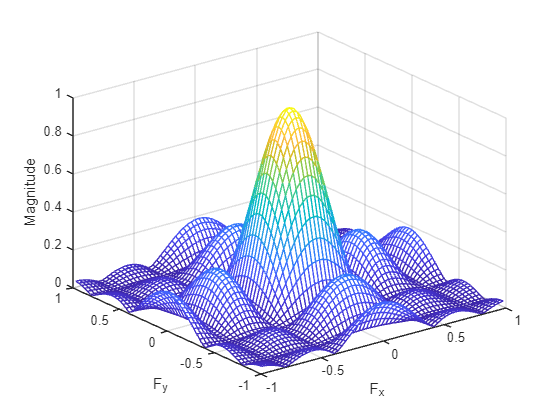

figure, freqz2(h)    %Escriba help freqz2 para obtener mas informacion sobre esta funcion

Hay que tener en cuenta que, tras aplicar algunas máscaras, es posible que la imagen de salida, de tipo double, denominada Y en el ejemplo anterior, tenga niveles fuera del intervalo [0—1] o [0—255]  (según la codificación de la imagen de entrada) pues algunos de estos filtros dan valores (bien positivos o negativos) superiores en módulo al nivel de gris máximo cuando detectan algún punto aislado, línea etc. Es fácil de ver si el rango de la imagen de salida está fuera del rango [0—1] o [0—255]  viendo el valor mínimo total de la imagen con min(min(Y)) y el máximo con max(max(Y).

Como solución:

1) Puede visualizar la nueva imagen con *imagesc* que escala los datos, aunque de forma interna y sólo de cara a la visualización, para usar todo el colormap (mapa de colores).

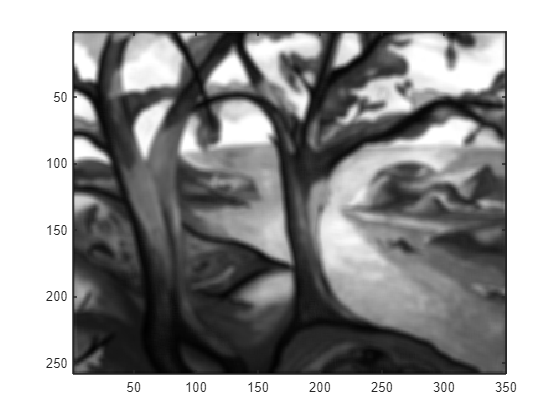

figure, colormap(gray(256)), imagesc(Y)

2) Puede normalizar la imagen de salida al rango [0-1],  restando a cada píxel el valor mínimo de toda la imagen y dividiendo por el rango o diferencia entre el valor máximo y mínimo, y luego visualizar del modo normal con imshow.

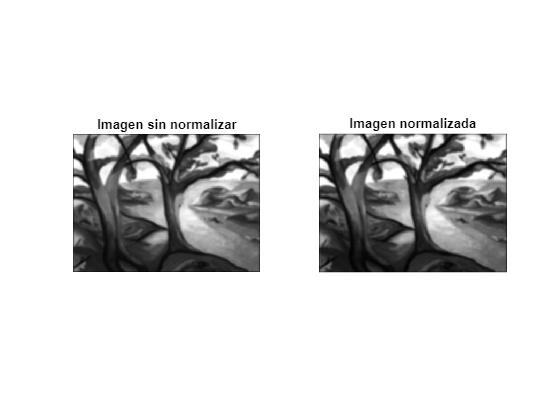

n_Y=(Y-min(min(Y)))/(max(max(Y))-min(min(Y)));
figure
subplot(1,2,1); imshow(Y); title ('Imagen sin normalizar');
subplot(1,2,2); imshow(n_Y); title ('Imagen normalizada');

**Pruebe los filtros con distintas imágenes comprobando los resultados.**

## Otros filtros lineales especiales. 

Algunos filtros mejoran las imágenes de manera especial. La rutina *fspecial* genera varios tipos de filtros predefinidos. Después de crear un filtro con *fspecial*, se aplica a los datos de la imagen utilizando *filter2*. Este ejemplo aplica un filtro 'average' a la imagen trees. 

load trees
I=ind2gray(X,map); %Imagen de intensidad double (rango de 0 a 1)
h=fspecial('average') 

h =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


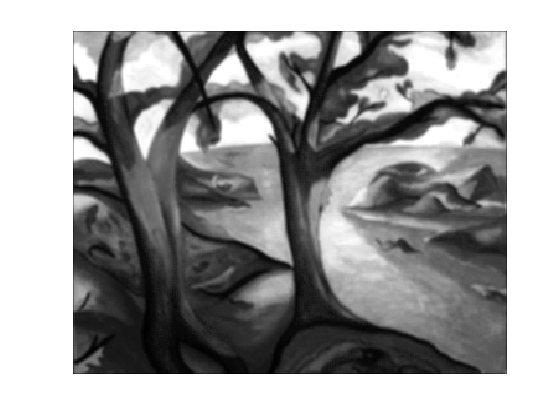

J=filter2(h,I);
figure, colormap(gray(128))
imagesc(J)
axis off

Algunos **filtros** que se pueden obtener con la función fspecial son: 

- 'gaussian'  for a Gaussian lowpass filter.

- 'average'   for an averaging filter.

- 'unsharp'   for an unsharp contrast enhancement filter.

- ...

**Pruebe con distintos filtros y distintas imágenes y extraiga conclusiones. **

## Filtrado de imágenes en color

Para filtrar una imagen en color se puede filtrar cada una de sus componentes R, G, B independientemente con un filtro (igual o distinto) para cada una de ellas. Además, debemos asegurarnos de que es del tipo adecuado, o realizar la conversión necesaria.

rgb=imread('.\imagenes\flowers.tif'); %Los valores R,G,B de la imagen rgb están entre 0 y 255 (uint8)
[filas, columnas, profundidad_color]=size(rgb) %Tamano de la imagen

filas = 362

columnas = 500

profundidad_color = 3

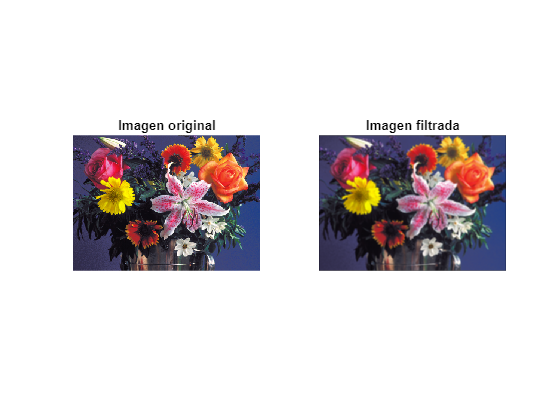

h=ones(5,5)/25;               %Mascara. Filtro paso bajo

% Extraemos cada componente
r=rgb(:,:,1);      %Los valores r están entre 0 y 255 (uint8)
g=rgb(:,:,2);      %Los valores g están entre 0 y 255 (uint8)
b=rgb(:,:,3);      %Los valores b están entre 0 y 255 (uint8)

% Filtramos cada color independientemente
n_r=filter2(h,r);  %Los valores n_r están entre 0'0 y 255'0 (double)
n_g=filter2(h,g);  %Los valores n_g están entre 0'0 y 255'0 (double)
n_b=filter2(h,b);  %Los valores n_b están entre 0'0 y 255'0 (double)

% Componemos la imagen final filtrada
rgb1=zeros(filas,columnas,profundidad_color); % rgb1 = imagen inicializada a ceros donde meter componentes filtradas
rgb1(:,:,1)=n_r;
rgb1(:,:,2)=n_g;
rgb1(:,:,3)=n_b;
rgb1=uint8(rgb1);    %Convierto la imagen a valores entre 0 y 255 de tipo uint8 (en vez de double)

figure;
subplot(1,2,1);imshow(rgb);title('Imagen original');
subplot(1,2,2);imshow(rgb1);title('Imagen filtrada');

O se puede aplicar el mismo filtro a las 3 componentes como se hace en el siguiente ejemplo (con una única función) con la función imfilter (versión 6.1 de Matlab o superior):

rgb=imread('.\imagenes\flowers.tif'); %Los valores R,G,B de la imagen rgb están entre 0 y 255 (uint8)
h=ones(5,5)/25;               %Mascara. Filtro paso bajo
rgb2=imfilter(rgb,h);      %Los valores R,G,B la imagen rgb2 están entre 0 y 255 (uint8)
%imfilter se puede usar tambien en imagenes en niveles de gris en lugar de filter2. Vea: help imfilter
figure,subplot(1,2,1),imshow(rgb),title('Imagen original');
subplot(1,2,2),imshow(rgb2),title('Imagen filtrada');

**Realice pruebas con distintos filtros sobre imágenes en color, comparando las imágenes de salida.**

## Filtrado de mediana. 

El filtrado mediana (mediante la función *medfilt2*) es útil para eliminar valores de píxeles extremos. Se trata de un tipo de filtro no lineal útil eliminar el ruido ‘salt & pepper’. 

Como ejemplo, se añadirá ruido del tipo “salt&peper” a una imagen y posteriormente se filtrará mediante un filtro media y un filtro mediana para que se observe la diferencia. 

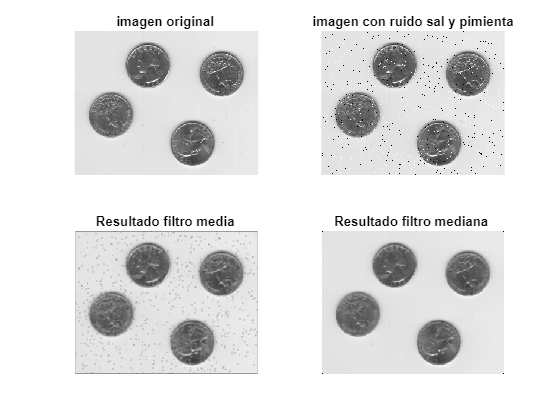

I=im2double(imread('.\imagenes\eight.tif'));
J=imnoise(I,'salt & pepper',0.02);  %Añade a imagen I ruido sal y pimienta de densidad 0.02
figure,subplot(2,2,1),imshow(I); title('imagen original ');
subplot(2,2,2), imshow(J);title('imagen con ruido sal y pimienta');
K=filter2(fspecial('average',3),J); %Filtro J con filtro promedio en entorno de vecindad 3x3
L=medfilt2(J,[3 3]); %Filtro imagen J con filtro mediana en entorno de vecindad 3x3
subplot(2,2,3), imshow(K); title('Resultado filtro media ');
subplot(2,2,4),imshow(L); title('Resultado filtro mediana ');

**Realice pruebas añadiendo a una imagen de entrada distintos tipos de ruido (con los parámetros de *****imnoise*****) y aplicando diferentes filtros para comprobar su eliminación en las imágenes de salida.**

## **Filtrado adaptativo Wiener.**

Este filtro paso-bajo adaptativo resulta útil para eliminar el ruido aditivo de potencia constante. 

El filtrado adaptativo Wiener (mediante la función *wiener2*) a menudo produce mejores resultados que el lineal: es más selectivo que dicho filtro, manteniendo bordes y otras partes de alta frecuencia de una imagen. Se adapta a la varianza local de la imagen. Donde ésta es mayor, el filtro Wiener realiza un suavizado menor. Donde la varianza es menor, realiza un mayor suavizado. 

Este ejemplo aplica el filtrado Wiener a la imagen degradada de saturno.  

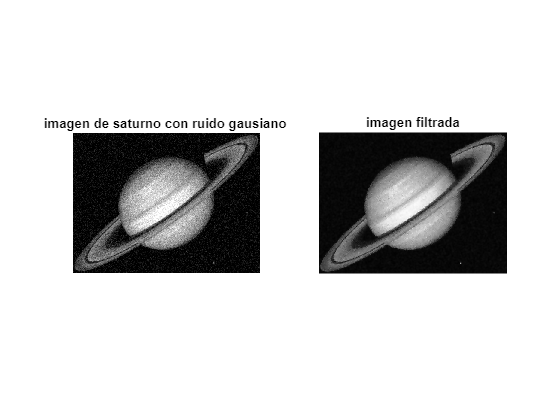

I=imread('.\imagenes\saturn.tif'); %Imagen de intensidad de tipo uint8 
%Uso la funcion imnoise que forma una nueva imagen tras añadir ruido a la original 
J=imnoise(I,'gaussian',0,0.005); %Añade a imagen I ruido gausiano de media 0 y varianza 0.005  
K=wiener2(J,[5 5]); %Filtro imagen ruidosa J con filtro wiener con entorno de vecindad [5 5] 
figure, 
subplot(1,2,1), imshow(J), title('imagen de saturno con ruido gausiano '); 
subplot(1,2,2), imshow(K); title('imagen filtrada');

**Realice pruebas cambiando las características del ruido (con los parámetros de *****imnoise*****) y comprobando su eliminación en las imágenes de salida.**